# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.17 Matlab制作动画效果的八个案例

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

**Matlab 制作动画效果的方法还挺多的，下面用 8 个案例来演示效果**

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();

## 案例一：重复绘图

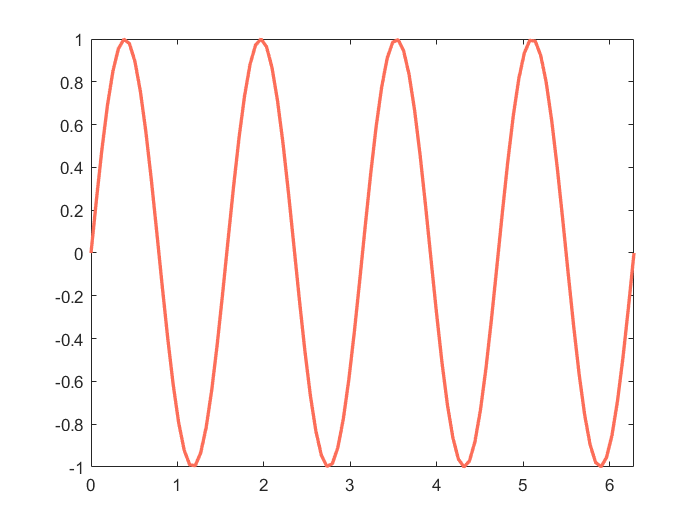

fig = figure;
x = linspace(0, 2*pi, 100);
im = cell(1, 20);
for i = 1:20
    y = sin(i*x/5);
    plot(x, y, 'Color', all_colors(1, :), 'LineWidth', 2);
    xlim([0, 2*pi]);
    pause(0.25);
    % 注释下面两句话可以看到动态输出
    frame = getframe(fig);
    im{i} = frame2im(frame);
end

% 下面是保存成 gif
filename = 'D:\MyPrograms\DataSet\程序运行截图\Matlab_2_7_6_Curve_Animation1.gif'; 
for idx = 1:20
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.3);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
    end
end

## 案例二：使用 animatedline 函数

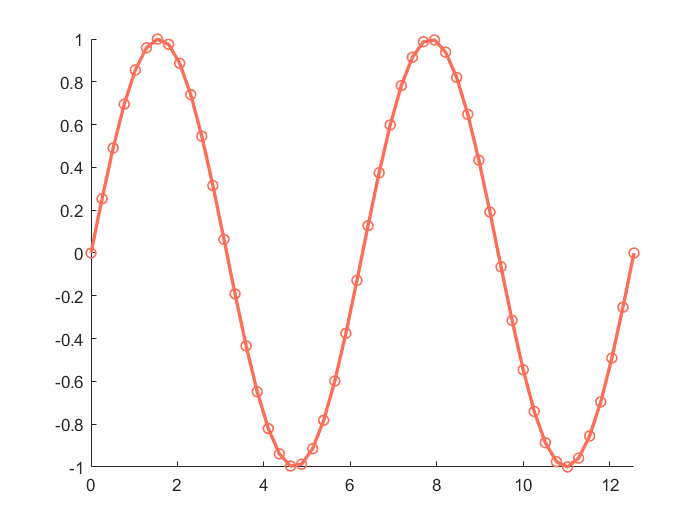

fig = figure;
h = animatedline('Color', all_colors(1, :), 'Marker', 'o', 'LineWidth', 2);
axis([0, 4*pi, -1, 1])
x = linspace(0, 4*pi, 50);
y = sin(x);
im = cell(1, length(x));
for k = 1:length(x)
    addpoints(h, x(k), y(k));
    drawnow
    % 注释下面两句话可以看到动态输出
    frame = getframe(fig);
    im{k} = frame2im(frame);
end

% 下面是保存成 gif
filename = 'D:\MyPrograms\DataSet\程序运行截图\Matlab_2_7_6_Curve_Animation2.gif'; 
for idx = 1:length(x)
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.3);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
    end
end

## 案例三：动态趋势线可视化

[https://zhuanlan.zhihu.com/p/138088420](https://zhuanlan.zhihu.com/p/138088420)

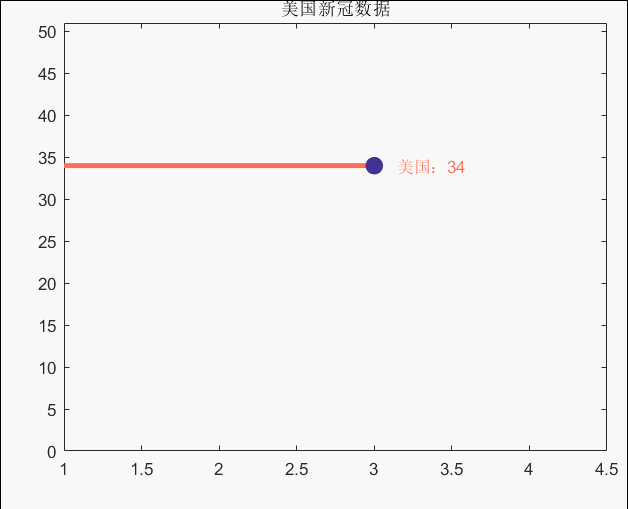

## 案例四：目标沿轨迹运动1

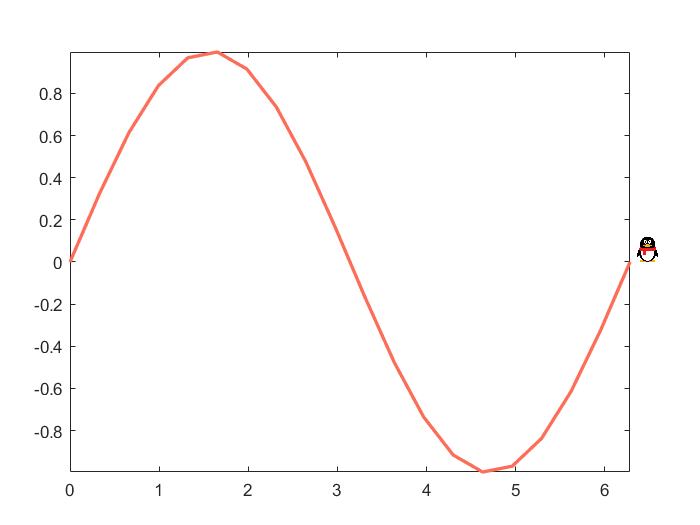

fig = figure;
% 生成轨迹
x = linspace(0, 2*pi, 20);
y = sin(x);
minX = min(x);
maxX = max(x);
minY = min(y);
maxY = max(y);
% 在特定位置绘制轨迹图
h1 = axes('position', [0.1, 0.1, 0.8, 0.8]);
plot(x, y, 'Color', all_colors(1, :), 'LineWidth', 2);
% 设置显示范围
xlim([minX, maxX]);
ylim([minY, maxY]);
% 图片尺寸
sizeQQ = 0.05;
posX = 0.1;
poxY = 0.85;
% 图像的位置
h2 = axes('position', [posX poxY sizeQQ sizeQQ]);
% 显示图片
imshow('data\qq.bmp');
im = cell(1, length(x));
for i = 1 : length(x)
    % 计算图片的位置
    posX = (x(i) - minX) / (maxX - minX) * 0.8 + 0.1;
    posY = (y(i) - minY) / (maxY - minY) * 0.8 + 0.1;
    % 删除之前的图片
    delete(h2);
    % 在新的位置显示
    h2 = axes('position', [posX posY sizeQQ sizeQQ]); 
    imshow('data\qq.bmp');
    % 暂停以显示动态过程
    pause(0.1);
    % 注释下面两句话可以看到动态输出
    frame = getframe(fig);
    im{i} = frame2im(frame);
end

% 下面是保存成 gif
filename = 'D:\MyPrograms\DataSet\程序运行截图\Matlab_2_7_6_Curve_Animation4.gif'; 
for idx = 1:length(x)
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.3);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
    end
end

## 案例五：标记点沿轨迹运动

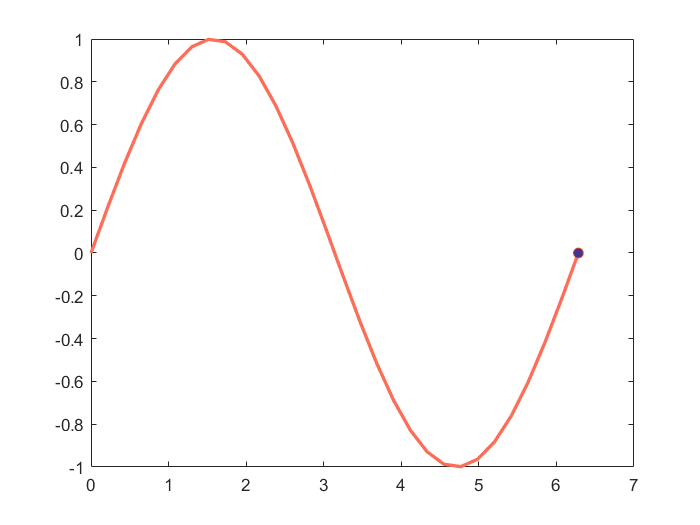

fig = figure;
% 生成轨迹
x = linspace(0, 2*pi, 30);
y = sin(x);
plot(x, y, 'Color', all_colors(1, :), 'LineWidth', 2);
hold on 
plt = plot(x(1), y(1), 'o', 'MarkerFaceColor', all_colors(6, :));
hold off
im = cell(1, length(x));
for i = 1 : length(x)
    plt.XData = x(i);
    plt.YData = y(i);
    % 暂停以显示动态过程
    pause(0.1);
    % 注释下面两句话可以看到动态输出
    frame = getframe(fig);
    im{i} = frame2im(frame);
end

% 下面是保存成 gif
filename = 'D:\MyPrograms\DataSet\程序运行截图\Matlab_2_7_6_Curve_Animation4.gif'; 
for idx = 1:length(x)
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.3);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
    end
end

## 案例六：目标沿轨迹运动2

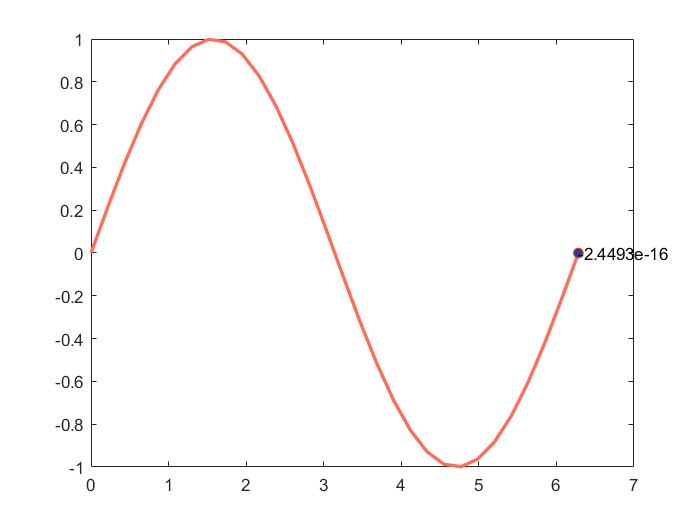

fig = figure;
% 生成轨迹
x = linspace(0, 2*pi, 30);
y = sin(x);
plot(x, y, 'Color', all_colors(1, :), 'LineWidth', 2);
h = hgtransform('Parent', gca);
hold on 
plot(x(1), y(1), 'o', 'Parent', h, 'MarkerFaceColor', all_colors(6, :));
hold off
txt = text(x(1), y(1), num2str(y(1)), 'Parent', h);
im = cell(1, length(x));
for i = 1 : length(x)
    % 平移操作
    h.Matrix = makehgtform('translate', x(i) - x(1), y(i) - y(1), 0);
    txt.String = num2str(y(i));
    % 暂停以显示动态过程
    pause(0.1);
    % 注释下面两句话可以看到动态输出
    frame = getframe(fig);
    im{i} = frame2im(frame);
end

% 下面是保存成 gif
filename = 'D:\MyPrograms\DataSet\程序运行截图\Matlab_2_7_6_Curve_Animation5.gif'; 
for idx = 1:length(x)
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.3);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
    end
end

## 案例七：图形对象动画

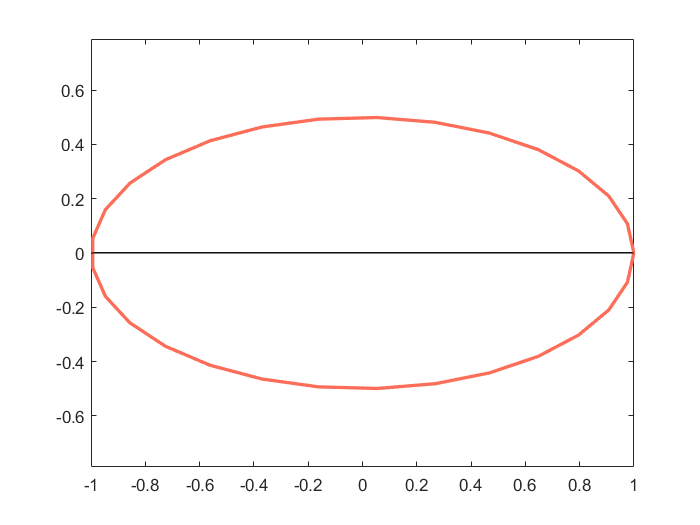

fig = figure;
% 生成轨迹
t = linspace(0, 2*pi, 30);
x = cos(t);
y = sin(t) / 2;
plot(x, y, 'Color', all_colors(1, :), 'LineWidth', 2);
axis equal
x1 = [-1, 0, 1];
y1 = [0, 0.5, 0];
hold on 
f = area(x1, y1);
hold off
im = cell(1, length(x));
for i = 1 : length(x)
    % 平移操作
    x1(2) = x(i);
    y1(2) = y(i);
    f.XData = x1;
    f.YData = y1;
    % 暂停以显示动态过程
    pause(0.1);
    % 注释下面两句话可以看到动态输出
    frame = getframe(fig);
    im{i} = frame2im(frame);
end

% 下面是保存成 gif
filename = 'D:\MyPrograms\DataSet\程序运行截图\Matlab_2_7_6_Curve_Animation6.gif'; 
for idx = 1:length(x)
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.3);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
    end
end

## 案例八：彗星图

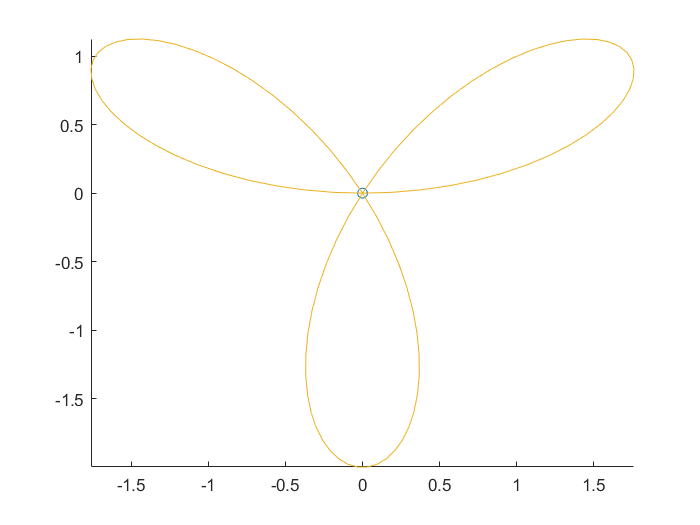

figure;
% 生成轨迹
t = linspace(0, 4*pi, 100);
x = -sin(t) - sin(t/2);
y = -cos(t) + cos(t/2);
comet(x, y);